% 人工亲本
parent1 = table2array(readtable("manual_parent.xlsx", 'Sheet', 'Sheet1'));
parent2 = table2array(readtable("manual_parent2.xlsx", 'Sheet', 'Sheet1'));

% constant
radius = 500;

theta = linspace(0, 2*pi, 1000);

x = radius * cos(theta);
y = radius * sin(theta);

point1 = [-1000, 0];
point2 = [3500, 0];


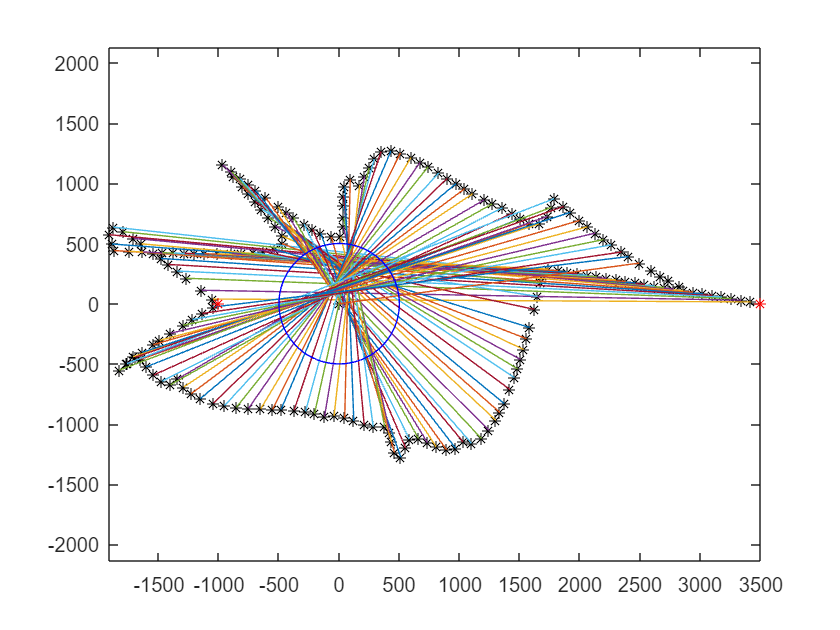

% 个体 zero(62, 2)
% 繁衍的群体
produced = zeros(25, 62, 2);
times = zeros(25,3);
% 经过筛选后的群体
filted = zeros(10, 62, 2);

best_individual = zeros(1, 63, 2);


flag = 1;
% 获取初始25个个体
while flag<26
    randomx_A = -2000 + 5500*rand(29, 1)'; 
    randomx_A = sort(randomx_A);
    randomx_B = -2000 + 5500*rand(29, 1)';
    randomx_B = sort(randomx_B);
    randomy_A = 1500 - 500*rand(29, 1)' - abs(randomx_A/3);
    randomy_B = -1500 + 500*rand(29, 1)' + abs(randomx_A/3);

    % 均衡
    %point_A = ([[-1000, randomx_A, 3500]', [0, randomy_A, 0]'] + parent1(1:31,:) )/2;   %parent2(1:31, :)
    %point_B = ([[3500, randomx_B(end:-1:1), -1000]', [0, randomy_B(end:-1:1), 0]'] + 2*parent1(32:62,:))/3;  %  + parent2(32:62, :)

    point_A = ([[-1000, randomx_A, 3500]', [0, randomy_A, 0]'] );
    point_B = ([[3500, randomx_B(end:-1:1), -1000]', [0, randomy_B(end:-1:1), 0]'] );

    [child1,child2] = hybird([point_A; point_B], parent); %[point_A; point_B]

    [time ,equal_point] = Bezier(child1(1:31, :), child1(32:62, :));
    if time(1)>0
        times(flag,1:2) = time;
        produced(flag, :, :) = child1;
        flag = flag+1;
    end

    if flag==26
        break;
    end

    [time ,equal_point] = Bezier(child2(1:31, :), child2(32:62, :));
    if time(1)>0
        times(flag,1:2) = time;
        produced(flag, :, :) = child2;
        flag = flag+1;
    end

end

clf

plot(equal_point(1, :, 1), equal_point(1, :, 2), '*k',  equal_point(2, :, 1), equal_point(2, :, 2), '*k')
hold on

for i=1:91
    plot([equal_point(1,i,1),equal_point(2, i, 1)], [equal_point(1,i,2), equal_point(2, i, 2)])
end

hold on
plot(x, y, 'b');
plot(point1(1), point1(2), '*r');
plot(point2(1), point2(2), '*r');
axis equal;

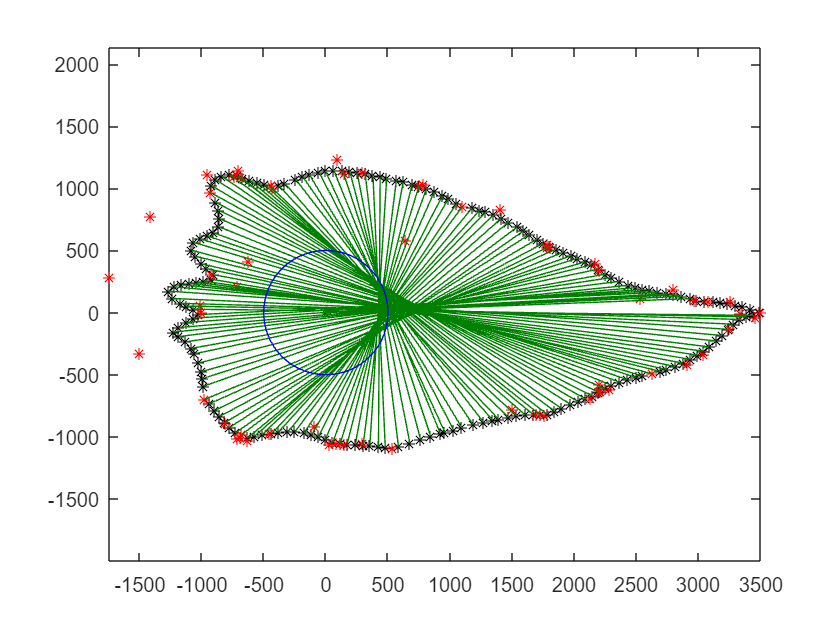


% 遗传主体
for i=1:100

    times(:, 3) = times(:,1) + times(:,2);
    times(:, 4) = 1:25;
    % 筛选10个优质个体
    times = sortrows(times,3);
    best_individual(i, 1:62, :) = produced(times(1,4), 1:62, :);
    best_individual(i, 63, :) = times(1, 1:2);
    for j=1:10
        filted(j, :, :) = produced(times(j,4), :, :);
    end

    % 精英策略：保留前五个为子代
    produced(1:5, :, :) = filted(1:5, :, :);

    % 杂交生成20个子代
    flag = 6;
    cur1 = 0; cur2 = 0;
    while flag<26

        cur1 = mod(cur1+1, 10)+1;
        cur2 = mod(cur2+3, 10)+1;
        [child1, child2] = hybird(reshape(filted(cur1, :, :), [], 2), reshape(filted(cur2, :, :), [], 2));

        [time ,equal_point] = Bezier(child1(1:31, :), child1(32:62, :));
        if time(1)>0
            times(flag,1:2) = time;
            produced(flag, :, :) = child1;
            flag = flag+1;
        end

        if flag==26
            break;
        end

        [time ,equal_point] = Bezier(child2(1:31, :), child2(32:62, :));
        if time(1)>0
            times(flag,1:2) = time;
            produced(flag, :, :) = child2;
            flag = flag+1;
        end

    end

end

generation = 100;


[time ,equal_point] = Bezier(reshape(best_individual(generation, 1:31, :), [], 2), reshape(best_individual(generation, 32:62, :), [], 2));

clf

plot(equal_point(1, :, 1), equal_point(1, :, 2), '*k',  equal_point(2, :, 1), equal_point(2, :, 2), '*k')
hold on
plot(best_individual(generation, :, 1), best_individual(generation, :, 2), '*r')
hold on

for i=1:91
    plot([equal_point(1,i,1),equal_point(2, i, 1)], [equal_point(1,i,2), equal_point(2, i, 2)], 'Color', [0 0.5 0])
end

hold on
plot(x, y, 'b');
plot(point1(1), point1(2), '*r');
plot(point2(1), point2(2), '*r');
axis equal;

clf
plot(point_A(:,1), point_A(:,2), '*k', point_B(:,1), point_B(:,2), '*b')
axis equal